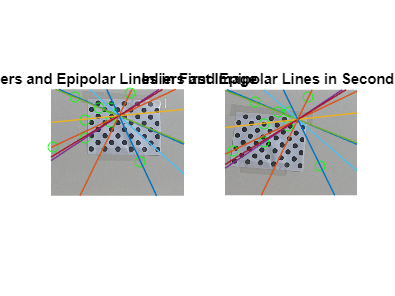

load stereoPointPairs
[fLMedS,inliers] = estimateFundamentalMatrix(matchedPoints1,...
    matchedPoints2,'NumTrials',4000);
I1 = imread('rgb_image0.jpg');
figure; 
subplot(121);
imshow(I1); 
title('Inliers and Epipolar Lines in First Image'); hold on;
plot(matchedPoints1(inliers,1),matchedPoints1(inliers,2),'go')
epiLines = epipolarLine(fLMedS',matchedPoints2(inliers,:));
points = lineToBorderPoints(epiLines,size(I1));
line(points(:,[1,3])',points(:,[2,4])');

I2 = imread('rgb_image15.jpg');
subplot(122); 
imshow(I2);
title('Inliers and Epipolar Lines in Second Image'); hold on;
plot(matchedPoints2(inliers,1),matchedPoints2(inliers,2),'go')
epiLines = epipolarLine(fLMedS,matchedPoints1(inliers,:));
points = lineToBorderPoints(epiLines,size(I2));
line(points(:,[1,3])',points(:,[2,4])');

fLMedS

fLMedS =     0.0000   -0.0004    0.0348
    0.0004    0.0000   -0.0937
   -0.0425    0.0993    0.9892
